# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Start with a clean session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report:

reportFile = 'Report.docx';
reportPlugin = TestReportPlugin.producingDOCX(reportFile); 
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFolder(pwd);
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING;
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp


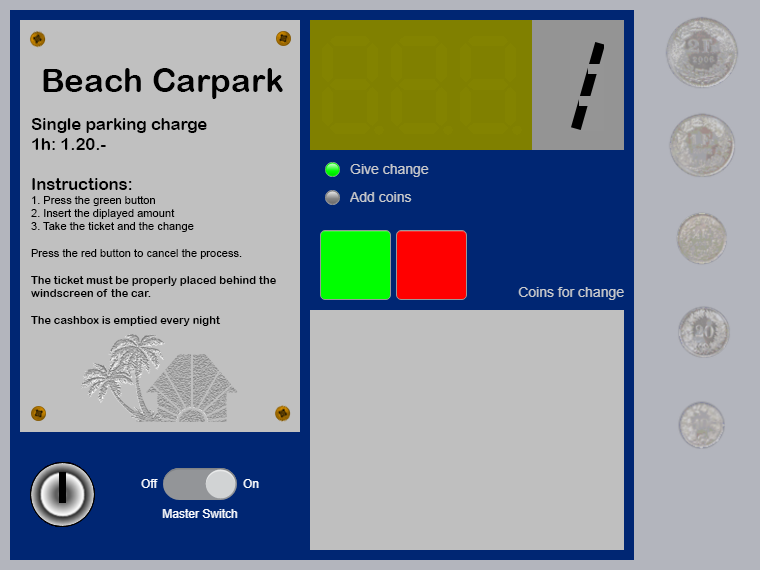

 Processing the test case #4...



Verification failed in TestApp/testCase_4_FullyEmptyAndReloadCashBox.
    ---------------------
    Framework Diagnostic:
    ---------------------
    verifyEqual failed.
    --> Path to failure: <Value>{13}
        --> The character arrays are not equal.
        
        Actual char:
             
        Expected char:
            0.10
    
    Actual Value:
      31×2 cell array
    
        {'DISP'}    {'COIN'}
        {'---' }    {' '   }
        {'1.20'}    {' '   }
        {'0.20'}    {' '   }
        {'0.10'}    {' '   }
        {' '   }    {'1.00'}
        {' '   }    {'0.50'}
        {' '   }    {'0.20'}
        {' '   }    {'0.20'}
        {'---' }    {' '   }
        {'1.20'}    {' '   }
        {'0.20'}    {' '   }
        

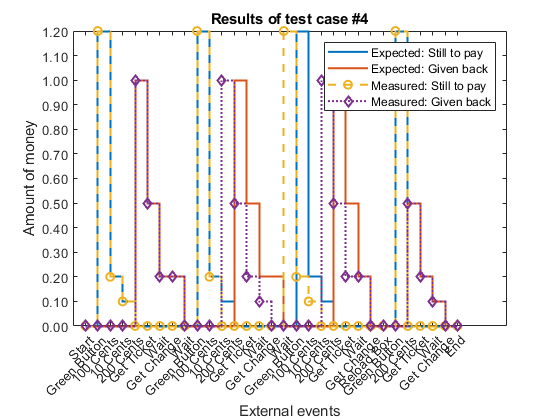

    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.docx
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tp7afa13c7_5b46_4c86_9375_c8767d91d2ac\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. See Results

disp(results.table);

Unable to resolve the name results.table.